## Gaussian Filter

A Gaussian filter assumes the noise added to the data follows a Gaussian distribution.

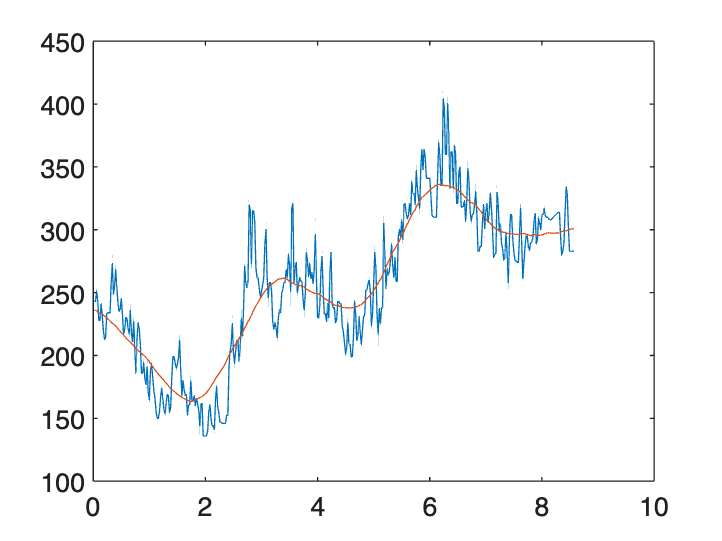

file = readmatrix("./input.csv");
time = file(:,1);
measurements = file(:,2);
standardDeviation = 34.415;

outputs = gaussianFilter(measurements, standardDeviation);

plot(time, measurements, time, outputs);

function outputs = gaussianFilter(inputs, standardDeviation)
  outputs = zeros(length(inputs), 1);

  % Kernel
  radius = floor(standardDeviation + 0.5);
  x = -radius:radius;
  kernel = exp(-(x.^2) / (2 * standardDeviation^2));
  kernel = kernel / sum(kernel);

  % Filter
  for n = 1:length(inputs)
      weightedSum = 0;
      sumWeights = 0;

      for j = -radius:radius
          index = n - j;
    
          if index < 1 || index > length(inputs)
              continue;
          end

          % Accumulate weighted sum
          weight = kernel(radius + 1 + j);
          weightedSum = weightedSum + inputs(index) * weight;
          sumWeights = sumWeights + weight;
      end

      outputs(n) = weightedSum / sumWeights;
  end
end
